# 去掉分段线性趋势实验

sigData：无线性趋势的信号

treData：两段线性趋势

mixData：信号数据+趋势数据

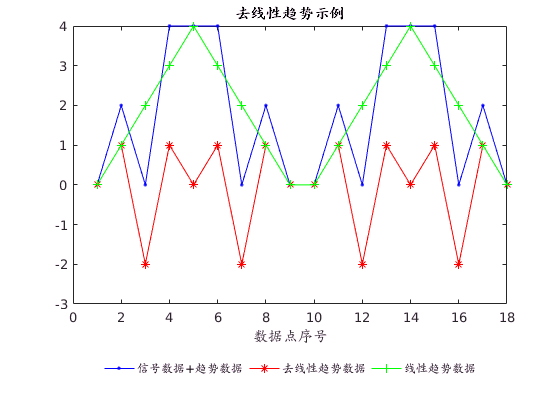

sigData = [0 1 -2 1 0 1 -2 1 0 0 1 -2 1 0 1 -2 1 0]; 
treData = [0 1 2 3 4 3 2 1 0 0 1 2 3 4 3 2 1 0];      
mixData = sigData+treData;  
%断点在第[5 9 10 14]个元素
detData = detrend(mixData,'linear',[5 9 10 14]); 

figure()
mp = plot(mixData,'b- .');
hold on
dp = plot(detData,'r- *');
hold on
tp = plot(treData,'g- +');
title('去线性趋势示例')
xlabel('数据点序号')
legend([mp dp tp],'信号数据+趋势数据','去线性趋势数据','线性趋势数据',...
                  'Location','southoutside','Orientation','horizontal');
legend('boxoff')